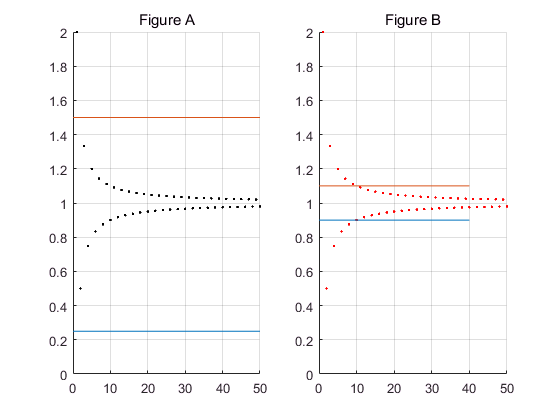

clf;
subplot(1, 2, 1);
hold on;
grid on;
n = 1:50;
m = (n + (-1).^(n-1))./n;
plot(n, m, 'k.');
fplot(@(t)0.25*ones(size(t)), [0 50]);
fplot(@(t)1.5*ones(size(t)), [0 50]);
axis([0 50 0 2]); 
title('Figure A');
hold off;

subplot(1, 2, 2);
hold on;
grid on;
plot(n, m, 'r.');
fplot(@(t)0.9*ones(size(t)), [0 40]);
fplot(@(t)1.1*ones(size(t)), [0 40]);
title('Figure B');
axis([0 50 0 2]); 

% Limit
syms x;
f1 = (x^3-1)/(x^2-5*x+3);
out = limit(f1);
disp(out);

$$-\frac{1}{3}$$


f2 = ((1+x)/x)^(2*x);
out = limit(f2, x, inf);
disp(out);

$${\mathrm{e}}^{2}$$

% Diff in MATLAB
syms x;
f = asin(1-2*x);
out = diff(f);
disp(out);

$$-\frac{2}{\sqrt{1-{\left(2\,x-1\right)}^{2}}}$$


syms x y z u;
u = (x-3*y)^z;
z = 2*x^2+y^2;
diff(u, x)

$$ans = z\,{\left(x-3\,y\right)}^{z-1}$$

diff(u, y)

$$ans = -3\,z\,{\left(x-3\,y\right)}^{z-1}$$

diff(diff(u, x), y)

$$ans = -3\,z\,{\left(x-3\,y\right)}^{z-2}\,\left(z-1\right)$$


syms x;
f = (3*x^2+4*x+4)/(x^2+x+1);
df = diff(f, x);
xz = solve(df);
disp(xz);

$$\left(\begin{array}{c} -2\\ 0 \end{array}\right)$$

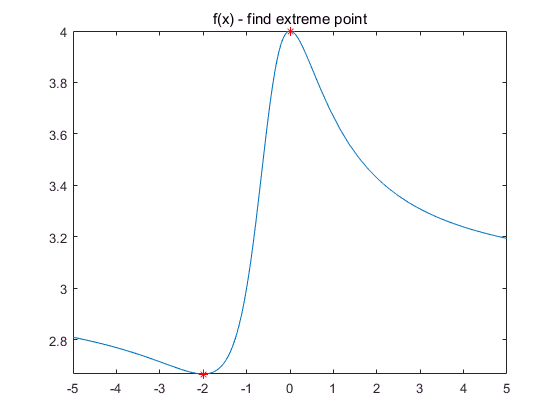

figure;
fplot(f);
hold on;
plot(xz, subs(f, xz), 'r*');
title('f(x) - find extreme point');
hold off;

syms x y;
fz = x^4-8*x*y+2*y^2-3;
dx = diff(fz, x);
dy = diff(fz, y);
[ex, ey] = solve(dx, dy, x, y);
disp(ex); disp(ey);

$$\left(\begin{array}{c} 0\\ -2\\ 2 \end{array}\right)$$

$$\left(\begin{array}{c} 0\\ -4\\ 4 \end{array}\right)$$

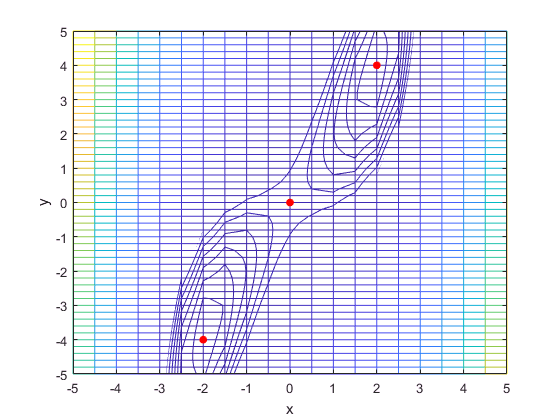


X = -5:0.5:5;
Y = -5:0.2:5;
[rx, ry] = meshgrid(X, Y);
rz = rx.^4-8.*rx.*ry+2.*ry.^2-3;
mesh(rx, ry, rz);
xlabel('x'); ylabel('y'); zlabel('z');
hold on;
plot3(ex, ey, subs(fz, {x, y}, {ex, ey}), 'r.', 'markersize', 20);
hold off;

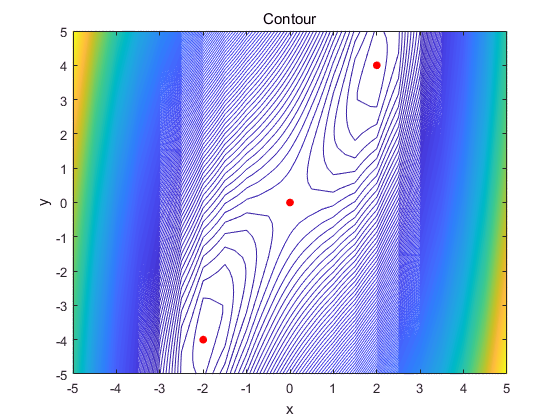


contour(rx, ry, rz, 300);
hold on;
plot(ex, ey, 'r.', 'markersize', 20);
xlabel('x'); ylabel('y');
title("Contour");
hold off;

% Indefinite integral
syms x;
f = (3*x^4+3*x^2+1)/(x^2+1);
out = int(f);
disp(f);

$$\frac{3\,x^{4}+3\,x^{2}+1}{x^{2}+1}$$

disp(out);

$$\mathrm{atan}\left(x\right)+x^{3}$$


syms x;
y = [cos(x),         x*exp(x);
    (2*x^2+3)/(2*x), tan(x)];
disp(y);

$$\left(\begin{array}{cc} \cos\left(x\right) & x\,{\mathrm{e}}^{x}\\ \frac{2\,x^{2}+3}{2\,x} & \tan\left(x\right) \end{array}\right)$$

out = int(y, x);
disp(out);

$$\left(\begin{array}{cc} \sin\left(x\right) & {\mathrm{e}}^{x}\,\left(x-1\right)\\ \frac{3\,\log\left(x\right)}{2}+\frac{x^{2}}{2} & -\log\left(\cos\left(x\right)\right) \end{array}\right)$$

syms x a c;
f = int((sin(a*x/4))^2 + x^3/5);
y = simplify(f) + c;
disp(y);

$$c+\frac{x}{2}-\frac{\sin\left(\frac{a\,x}{2}\right)}{a}+\frac{x^{4}}{20}$$

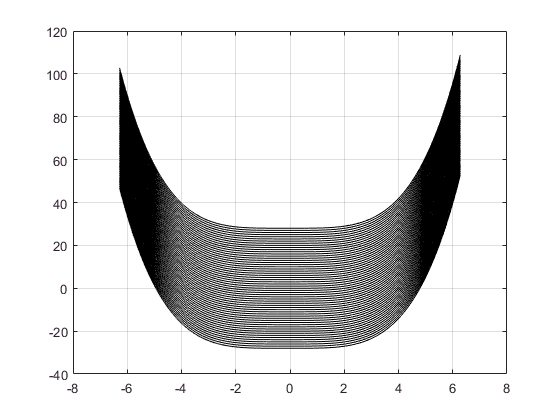


A = 1;
X = -2*pi:0.01:2*pi;
for C = -28:28
   Y = C + X./2 - sin(A.*X./2)./A + X.^4./20;
   plot(X, Y, 'k');
   hold on;
end
grid;
hold off;